clc;clear;close all
load fisheriris.mat


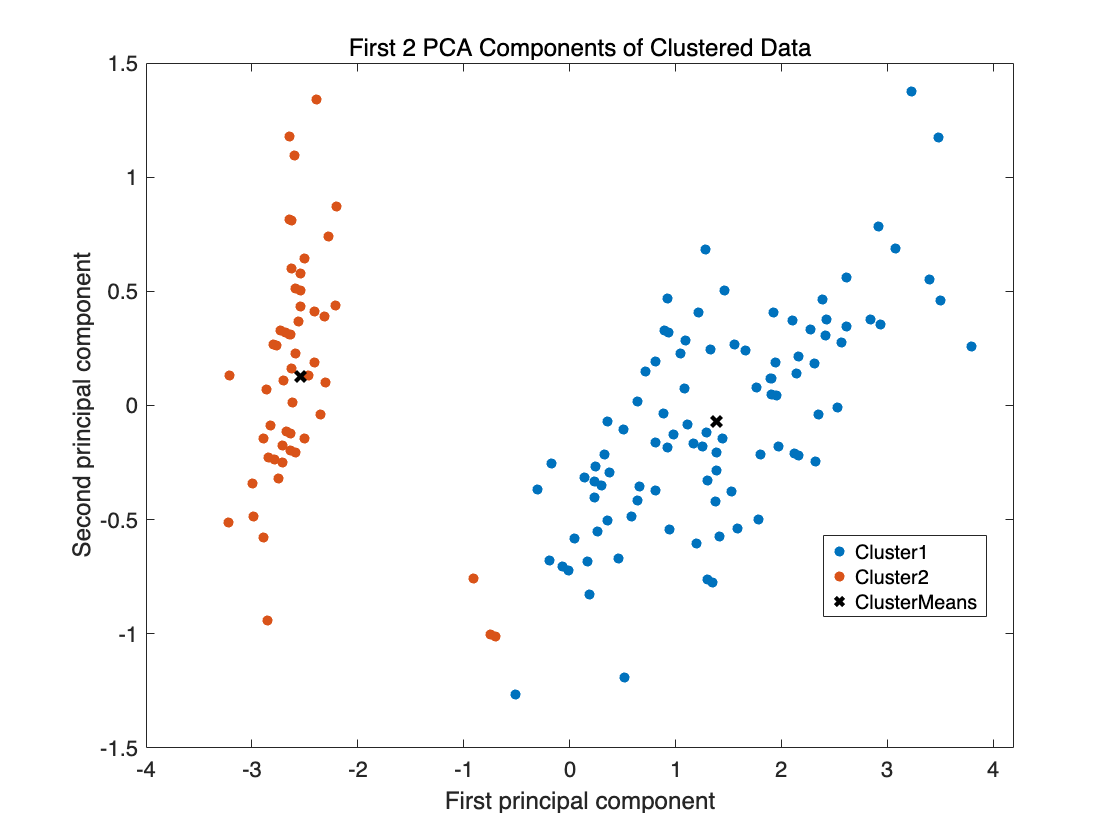

% 使用指定的簇个数执行 K 均值聚类(K 值)
K = 2;
[clusterIndices,centroids] = kmeans(meas,K);
clear K

% 显示结果

% 显示二维散点图(PCA)
figure
[~,score] = pca(meas);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");